# Trabalho 3 - Realimentação de estados

## Nome: (coloque seu nome aqui)

## Data limite para entrega: 18/07, 23h59min

**Importante lembrar:**

- Entrega após a data/horário acima: a nota será multiplicada por $1-e^{-30/h}$, onde h são as horas em atraso (Exemplo: 24h, multiplica por 0.71).

- O trabalho não é recebido por email

- Cabe a vocês garantir que o documento entregue é um arquivo pdf legível, e que não foi entregue com erro. Para isto, basta depositar e abrir para conferir.

- Código é apenas uma informação complementar, e não é considerada parte da solução para fins de avaliação.

- Caso não haja tempo de fazer todo o trabalho, entregue no prazo o que estiver pronto.

I=0;
[G,tse,sat]=init_t3(I);

**Atividade 1) **Seja o sistema em variáveis de estados


$$\dot{x}=Ax+Bu$$



$$y=Cx$$


sendo que $G(s)=C(sI-A)^{-1}B$.

Obtenha a realimentação de estados da forma  $u(t)=\rho r(t)-Kx(t)$ tal que a saída tenha sobreelevação $UP\leq 4.3\%$ e o tempo de estabelecimento seja $\leq t_{se}$. Deve-se ajustar o ganho da FT de malha fechada com $\rho$ de modo que a saída tenda para a referência unitária.  

Faz parte da resposta:

- Explicar como escolheu os 3 polos de malha fechada.

- Obter a FT de malha fechada Y/R e seu ganho.

- Verificar se houve saturação no sinal de controle u(t) e caso sim,  como isso afetou a resposta. 

- Verificar a relação em regime $y(\infty)=G(0)u(\infty)$, onde $y(\infty)$ e $u(\infty)$são os valores em regime obtidos da simulação.

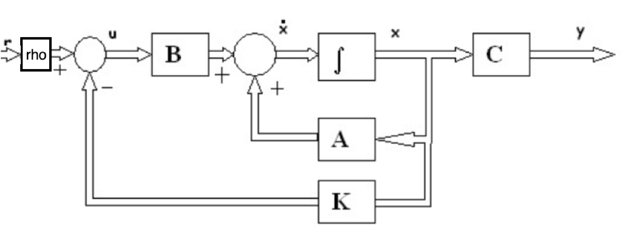

Função fornecida para a simulação: 

[y,t,u]=simula_te(s1,K,rho,sat)

y = saída     t = tempo   u = sinal de controle

s1 = sistema em variáveis de estados obtido de G

K = realimentação de estados 

rho = multiplicador de r(t) para garantir saida = referência em regime

sat = saturação do sinal de controle, fornecido por init_t3

% Obtenha aqui o modelo em variaveis de estado s1, escolha os polos e calcule
% a realimentacao K e rho

[y,t,u]=simula_t3(s1,K,rho,sat);
S=stepinfo(y,t);
tity=sprintf('Saida Ts=%0.2f  UP=%0.2f',S.SettlingTime, S.Overshoot);
subplot(211);plot(t,y);title(tity);xline(tse,'r');xline(S.SettlingTime,'b');
subplot(212);plot(t,u);
title('Sinal de controle');xlabel('Tempo(s)');

**Atividade 2) **Seja o mesmo sistema da atividade 1) e uma realimentação integral de estados da forma $u(t) = -K_1\bar{x}$, sendo $\bar{x}$ o estado aumentado com o integrador. O erro para entrada degrau deve ser zero com a mesma especificação de UP e Ts da atividade 1.

Faz parte da resposta:

- Explicar como escolheu os 4 polos de malha fechada.

- Obter a FT de malha fechada Y/R e seu ganho

- Verificar se houve saturação no sinal de controle u(t) e caso sim, como isso afetou a resposta.

- Explicar o sinal de erro, o que garante que ele tenda a zero e qual sua relação com o estado $x_4$.

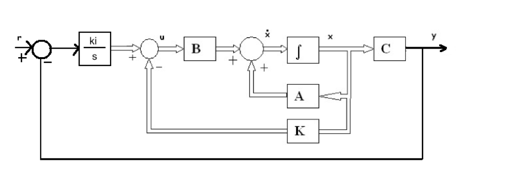

% Obtenha aqui o modelo em variaveis de estado aumentado s1i, escolha os polos e calcule
% a realimentacao integral de estados K1 


[y,t,u,X]=simula_t3(s1i,K1,1,sat);
S=stepinfo(y,t);
tity=sprintf('Saida Ts=%0.2f  UP=%0.2f',S.SettlingTime, S.Overshoot);
figure;
subplot(211);plot(t,y);title(tity);xline(ts_ma/5,'r');xline(S.SettlingTime,'b');
subplot(212);plot(t,u);title('Sinal de controle');xlabel('Tempo(s)');
figure
plot(t,X);title('Estados');
legend('x_1','x_2','x_3','x_4')
figure;
plot(t,1-y);
title('Erro=R-Y');xlabel('Tempo(s)');